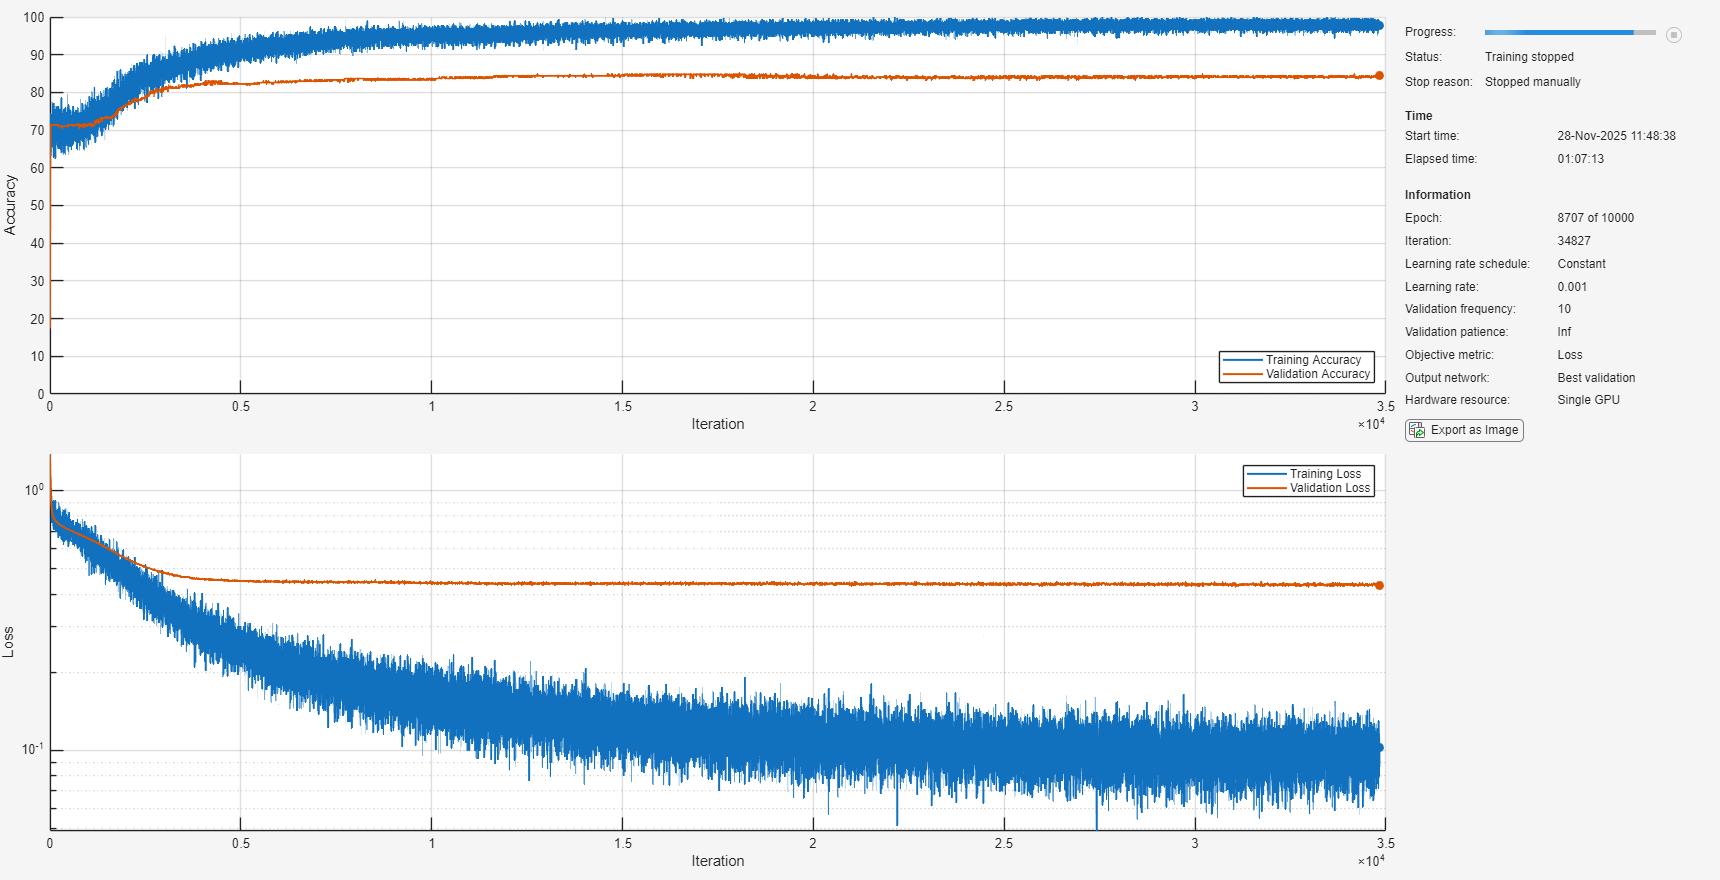

%% train_car_eval_release.m
% Public-ready script for classifying the UCI Car Evaluation dataset with a
% frozen NAR-style network (two fixed tanh FC blocks + softmax head).
%
% Dataset
% -------
% UCI Machine Learning Repository:
%   "Car Evaluation"
%   URL: https://archive.ics.uci.edu/dataset/19/car+evaluation
%
% How to obtain & prepare the data
% --------------------------------
% 1) Manual download (web UI):
%    - Visit the URL above and download the raw file (commonly named 'car.data').
%    - Put it under: ./data/uci_car/
%    - In MATLAB, run:
%         prepare_car_mat_from_uci('./data/uci_car', './data/car_dataset.mat');
%
% 2) If you already have car.data (or an equivalent CSV) locally:
%       prepare_car_mat_from_uci('/path/to/folder_or_csv', './data/car_dataset.mat');
%
% Expected MAT file
% -----------------
% This script expects ./data/car_dataset.mat to contain a variable 'data'
% as a NUMERIC matrix shaped [N x 7] with:
%   - Columns 1..6 : encoded categorical features as integers
%   - Column 7     : encoded class labels as integers in {1..K}
% The helper below reads the raw categorical file and encodes each column
% consistently into integers so it matches this interface exactly.
%
% Usage
% -----
%   train_car_eval_release
%
% Notes
% -----
% * Requires: MATLAB R2023b+ and Deep Learning Toolbox.
% * Custom initializers: uses your original functions
%     customWeights1 / customWeights2 / customWeights3
%   Ensure these are on the MATLAB path (same folder or +package).
% * Plots: keeps MATLAB's training-progress window and shows evaluation
%   confusion matrices; nothing is saved to disk.

%% -------------------- User-configurable section --------------------
RESULTS_DIR = './';
DATA_DIR    = './';
MAT_PATH   = fullfile(DATA_DIR, 'car_dataset.mat');
WIDTH      = 16000;   % reduce (e.g., 2048) if memory-constrained
MAX_EPOCHS = 10000;
LR         = 0.001;
MINIBATCH  = 256;

%% -------------------------- Main routine --------------------------
clearvars -except DATA_DIR MAT_PATH WIDTH MAX_EPOCHS LR MINIBATCH
close all; clc; rng(42,'twister');

% If needed, build the MAT from raw UCI file
if ~isfile(MAT_PATH)
    warning('MAT not found at %s. Attempting to prepare from UCI folder...', MAT_PATH);
    prepare_car_mat_from_uci(fullfile(DATA_DIR,'uci_car'), MAT_PATH);
end

S = load(MAT_PATH);
assert(isfield(S,'data'), 'MAT must contain variable ''data'' as numeric [N x 7].');
data = S.data;

% Labels and features
labels = categorical(data(:,7));        % integer codes -> categorical
% Guard against NaNs (should not occur after encoding, but keep parity with your pattern)
data(~isfinite(data)) = 0;
X = data(:,1:6)';                         % features C x N (C=6)

% Normalize features (zero mean, unit variance) scaled by 1/sqrt(C)
C = size(X,1);
X = (1/sqrt(C)) * ((X - mean(X,2)) ./ std(X,0,2));
X(~isfinite(X)) = 0;

% Split: 80/20 train/test, then 80/20 of train for validation
N = size(X,2);
cv1 = cvpartition(N,'HoldOut',0.2);
XTrainFull = X(:, training(cv1));
YTrainFull = labels(training(cv1));
XTest      = X(:, test(cv1));
YTest      = labels(test(cv1));

cv2 = cvpartition(sum(training(cv1)),'HoldOut',0.2);
XTrain = XTrainFull(:, training(cv2));
YTrain = YTrainFull(training(cv2));
XVal   = XTrainFull(:, test(cv2));
YVal   = YTrainFull(test(cv2));

% Number of classes from training labels
K = numel(categories(YTrain));

% Define network (two frozen FC tanh layers + softmax output)
% Initializers: your custom functions customWeights1/2/3
layers = [
    featureInputLayer(size(XTrain,1), Normalization='none')
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights1_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights2_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(K, 'Name','output', ...
        'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights3_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    softmaxLayer];

net = dlnetwork(layers);

% Convert to dlarray
XTrain_dl = dlarray(single(XTrain), 'CB');
XVal_dl   = dlarray(single(XVal),   'CB');

% Training options (keep training-progress; no saving)
options = trainingOptions('adam', ...
    'MaxEpochs', MAX_EPOCHS, ...
    'Metrics', ["accuracy"], ...
    'MiniBatchSize', MINIBATCH, ...
    'InitialLearnRate', LR, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YVal}, ...
    'ValidationFrequency', 10, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment','auto', ...
    'Verbose', 0);

[net, info] = trainnet(XTrain_dl, YTrain, net, 'crossentropy', options); %#ok<NASGU>


% Test-time evaluation
XTest_dl = dlarray(single(XTest), 'CB');
scores = predict(net, XTest_dl);
[~, idx] = max(scores, [], 1);
predictedLabels = categorical(idx(:), 1:K, categories(YTrain));

acc = mean(predictedLabels == YTest);
fprintf('Test Accuracy: %.2f%%\n', 100*acc);

Test Accuracy: 85.51%


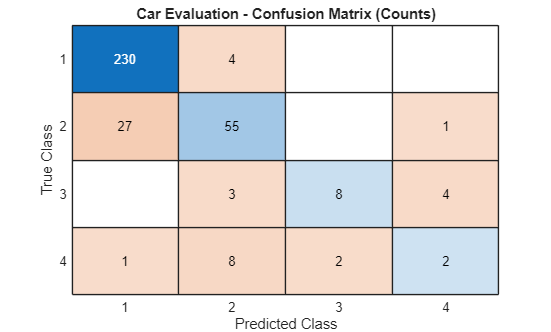


% Confusion matrices (on screen only)
figure('Name','Confusion Matrix (Counts)','Color','w');
confusionchart(YTest, predictedLabels);
title('Car Evaluation - Confusion Matrix (Counts)');

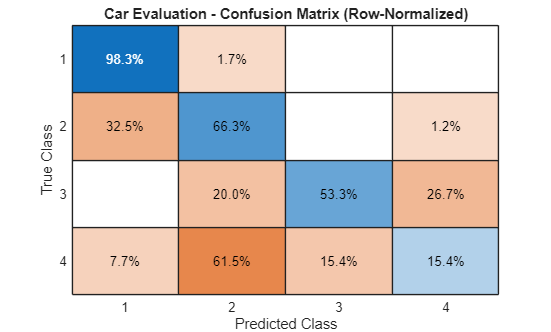


figure('Name','Confusion Matrix (Row-Normalized)','Color','w');
confusionchart(YTest, predictedLabels, 'Normalization','row-normalized');
title('Car Evaluation - Confusion Matrix (Row-Normalized)');


%% ------------------------ Helper functions ------------------------
function prepare_car_mat_from_uci(inDirOrFile, outMat)
% Build ./data/car_dataset.mat with numeric 'data' [N x 7] from the raw
% UCI Car Evaluation file (car.data). Each column is categorical; we encode
% each column to integers (1..K). Column 7 is the class label.
    if isfolder(inDirOrFile)
        d = dir(fullfile(inDirOrFile,'*.data'));
        if isempty(d); d = dir(fullfile(inDirOrFile,'*.csv')); end
        assert(~isempty(d), 'No .data or .csv file found in %s', inDirOrFile);
        [~,i] = max([d.bytes]); csvPath = fullfile(d(i).folder, d(i).name);
    else
        csvPath = inDirOrFile;
    end
    assert(isfile(csvPath), 'File not found: %s', csvPath);

    % Read raw (no headers); expect 7 categorical columns
    T = readtable(csvPath, 'FileType','text', 'ReadVariableNames', false);
    assert(width(T) >= 7, 'Expected 7 columns in car.data');
    T = T(:,1:7);

    % Encode each column to integer codes 1..K using categorical
    M = zeros(height(T), 7);
    for j = 1:7
        cj = categorical(T{:,j});
        [~,~,g] = unique(cj, 'stable');
        M(:,j) = double(g);
    end

    data = M; 
    outDir = fileparts(outMat);
    if ~isempty(outDir) && ~exist(outDir,'dir'); mkdir(outDir); end
    save(outMat,'data','-v7.3');
    fprintf('Wrote %s (rows=%d)\n', outMat, size(M,1));
end
